# MATLAB Reproducibility Survey Analysis

% Read in raw data file.
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames')
rawData = readtable(fullfile("data", "raw", "anonymised_responses.csv"),...
    'VariableNamingRule','modify');
% Remove non-sensical responses
cleanedData = rawData;
cleanedData([112, 113, 168, 174:179, 206], :) = [];

% Rename columns
cleanedData = renameColumns(cleanedData);

% Make institution names uniform
cleanedData.institution = tidyInstitutions(cleanedData.institution);


## MATLAB and Programming Expertise

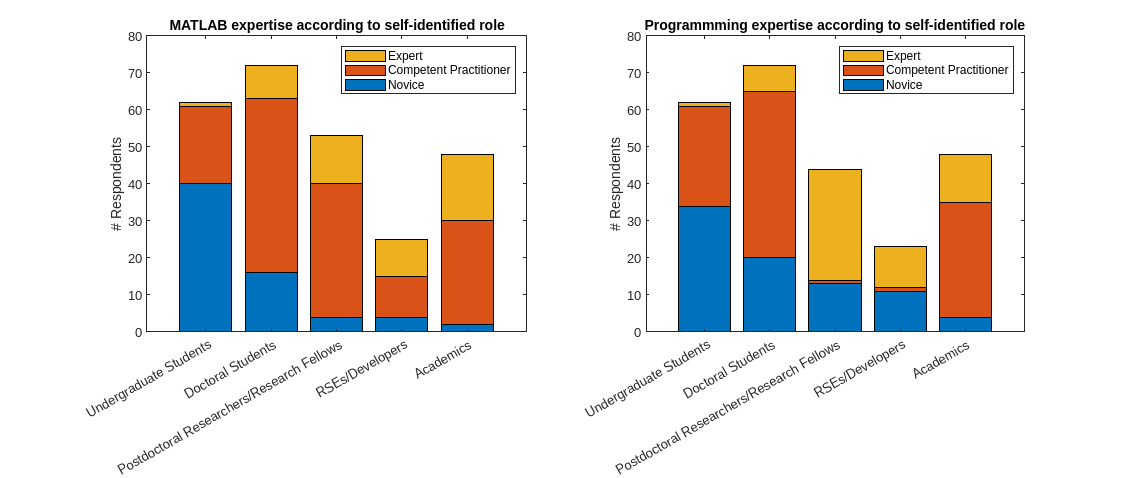

plotExperienceCharts(cleanedData)
set(gcf,'Units','normalized','Position',[0 0 1 1.5]); 

## Awareness of and Use of Version Control

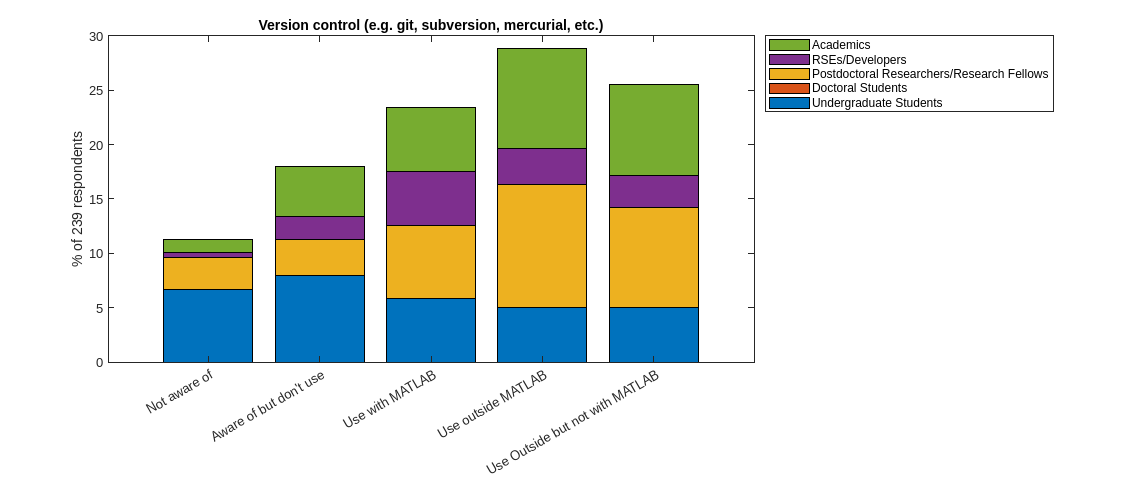

awarenessTable = cleanedData(:, {'role', 'matlabExperience', 'programmingExperience', 'awareness_versionControl', 'awareness_github', 'awareness_CICD', 'awareness_dataAvailability', 'awareness_dependencyMgmt', 'awareness_literateProgramming', 'awareness_docGen', 'awareness_softwareTesting'});

plotAwareness(awarenessTable, "awareness_versionControl")
title("Version control (e.g. git, subversion, mercurial, etc.)")

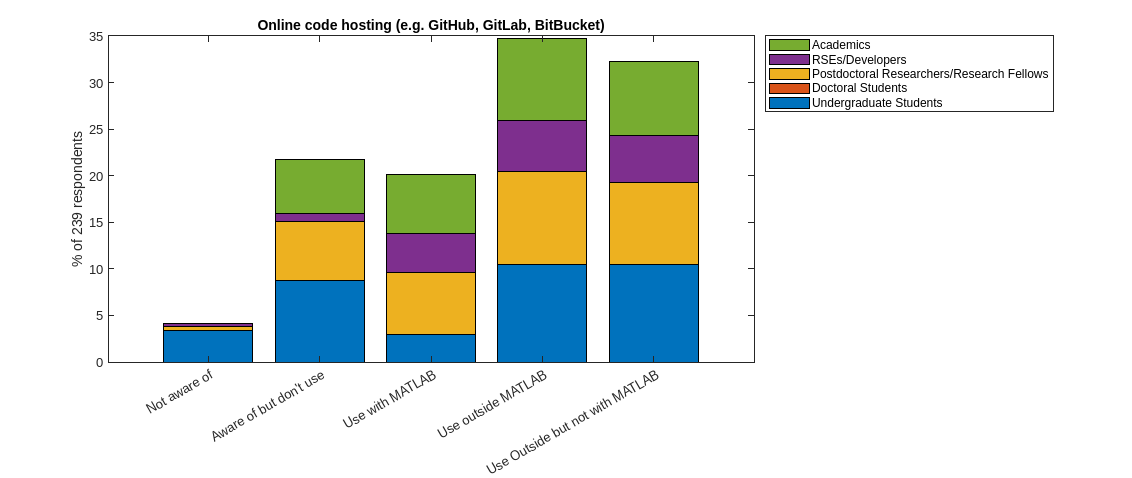

plotAwareness(awarenessTable, "awareness_github")
title("Online code hosting (e.g. GitHub, GitLab, BitBucket)")

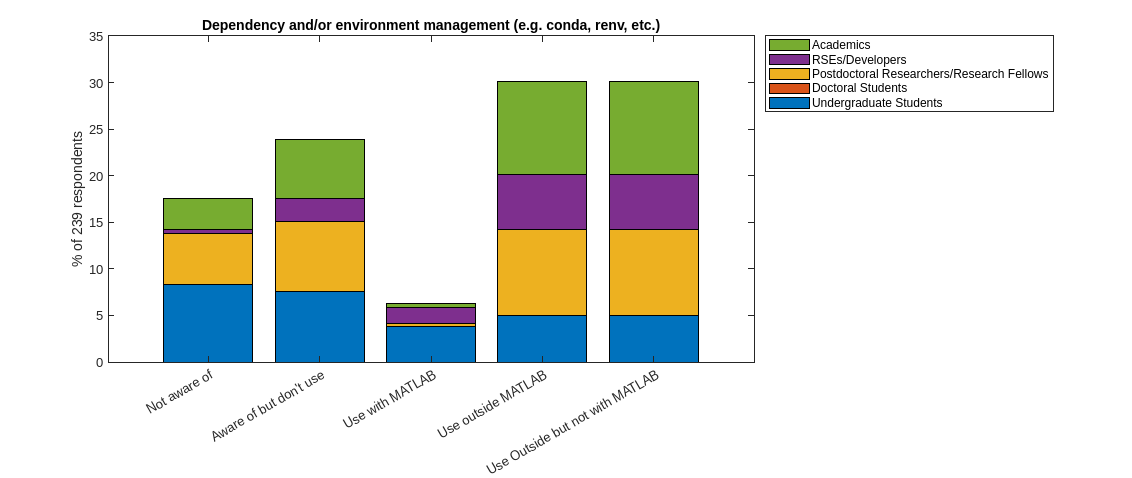

plotAwareness(awarenessTable, "awareness_dependencyMgmt")
title("Dependency and/or environment management (e.g. conda, renv, etc.)")

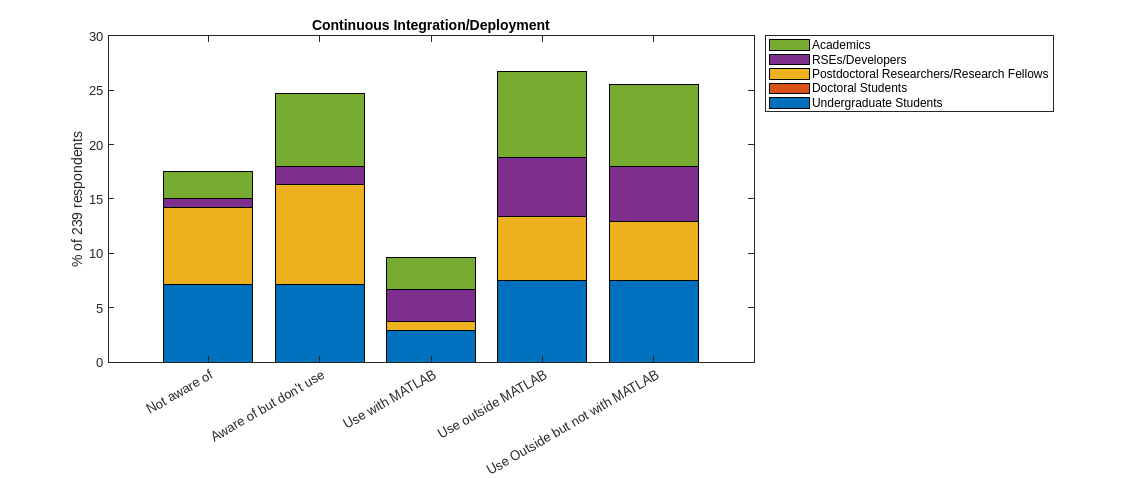

plotAwareness(awarenessTable, "awareness_CICD")
title("Continuous Integration/Deployment")

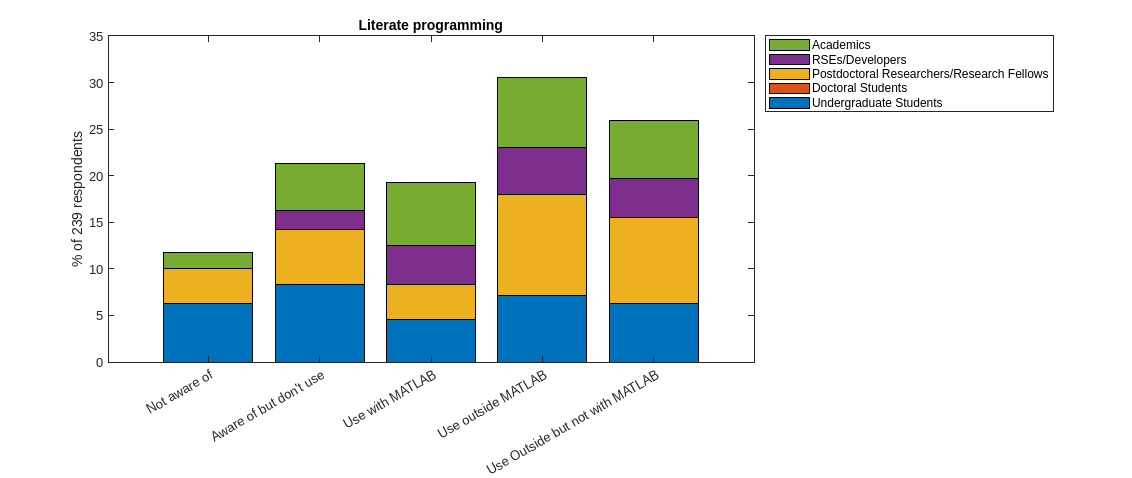

plotAwareness(awarenessTable, "awareness_literateProgramming")
title("Literate programming")

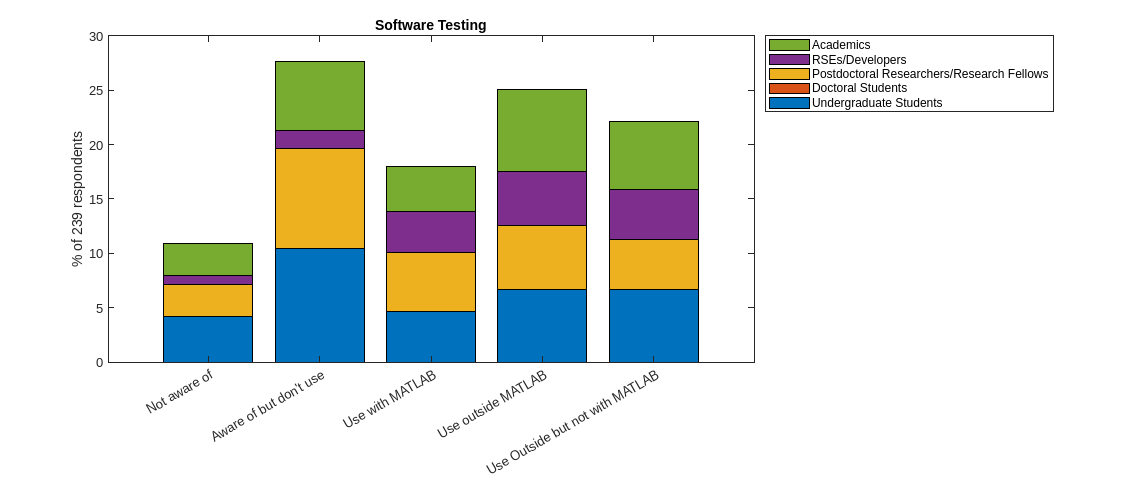

plotAwareness(awarenessTable, "awareness_softwareTesting")
title("Software Testing")

## Usage of Git with MATLAB

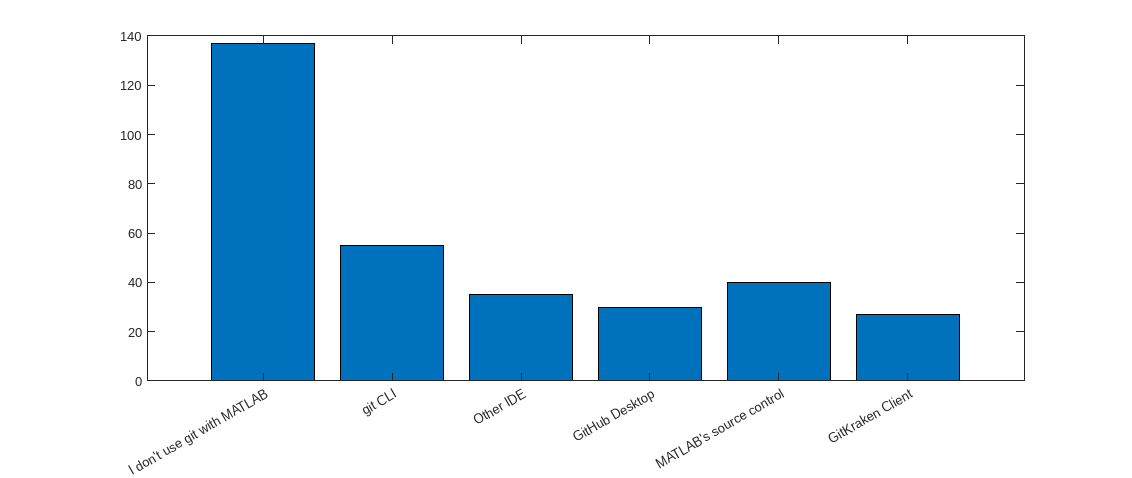

gitTable = cleanedData(:, {'role', 'matlabExperience', 'programmingExperience', 'gitUsage'});

%  Do you use git as a version control system with MATLAB? If so, which interface(s) do you use?

barVals = [height(gitTable(contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    height(gitTable(contains(gitTable.gitUsage, "git's command line interface") & ~contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    height(gitTable(contains(gitTable.gitUsage, "Other development environment git interface (e.g. VScode, Rstudio, PyCharm)") & ~contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    height(gitTable(contains(gitTable.gitUsage, "GitHub Desktop") & ~contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    height(gitTable(contains(gitTable.gitUsage, "MATLAB's source control tools") & ~contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    height(gitTable(contains(gitTable.gitUsage, "GitKraken Client") & ~contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    ];

labels = {'I don''t use git with MATLAB', 'git CLI', 'Other IDE', 'GitHub Desktop','MATLAB''s source control', 'GitKraken Client'};
x = categorical(labels);
x = reordercats(x,labels);

bar(x, barVals)

## Usage of MATLAB Tools and Features

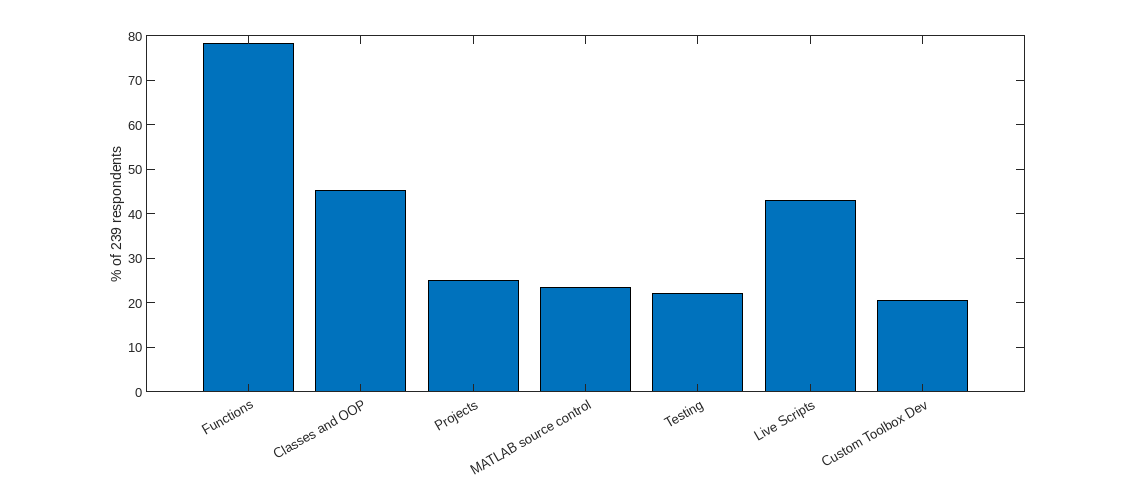

matlabToolsTable = cleanedData(:, {'role', 'matlabExperience', 'programmingExperience', 'matlabFeatures'});

%  Do you use git as a version control system with MATLAB? If so, which interface(s) do you use?

barVals = 100*[height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Functions"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Classes and Object-Oriented Programming"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Projects"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "MATLAB's source control integration"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Testing"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Live Scripts"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Custom toolbox development"), :)) ...
    ]/height(matlabToolsTable);

labels = {'Functions', 'Classes and OOP', 'Projects', 'MATLAB source control', 'Testing', 'Live Scripts', 'Custom Toolbox Dev'};
x = categorical(labels);
x = reordercats(x,labels);

bar(x, barVals)

ylabel(strcat("% of ", num2str(height(matlabToolsTable)), " respondents"))

## Demand for training

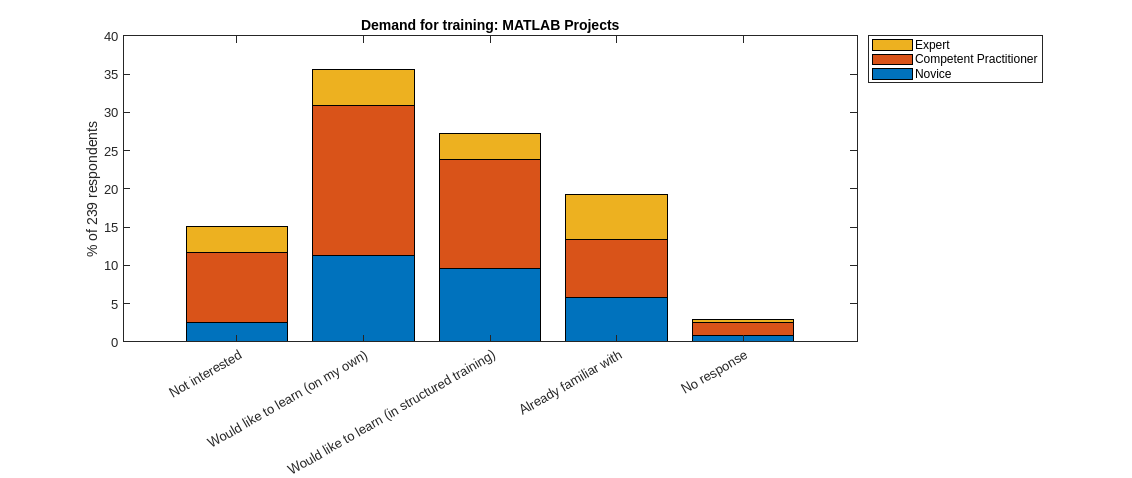

plotTrainingDemand(cleanedData, "trainingDemand_projects")
title("Demand for training: MATLAB Projects")

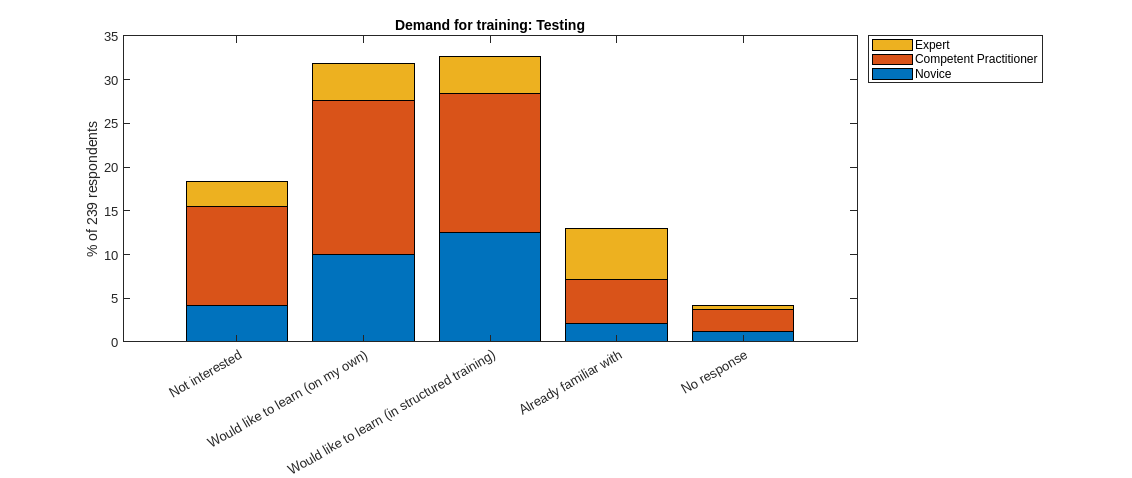

plotTrainingDemand(cleanedData, "trainingDemand_testing")
title("Demand for training: Testing")

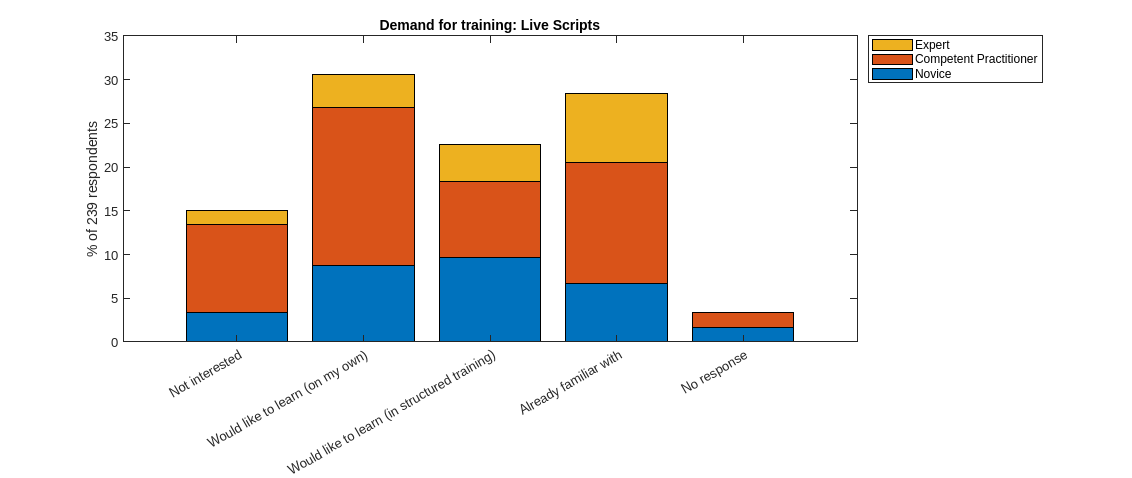

plotTrainingDemand(cleanedData, "trainingDemand_livescripts")
title("Demand for training: Live Scripts")

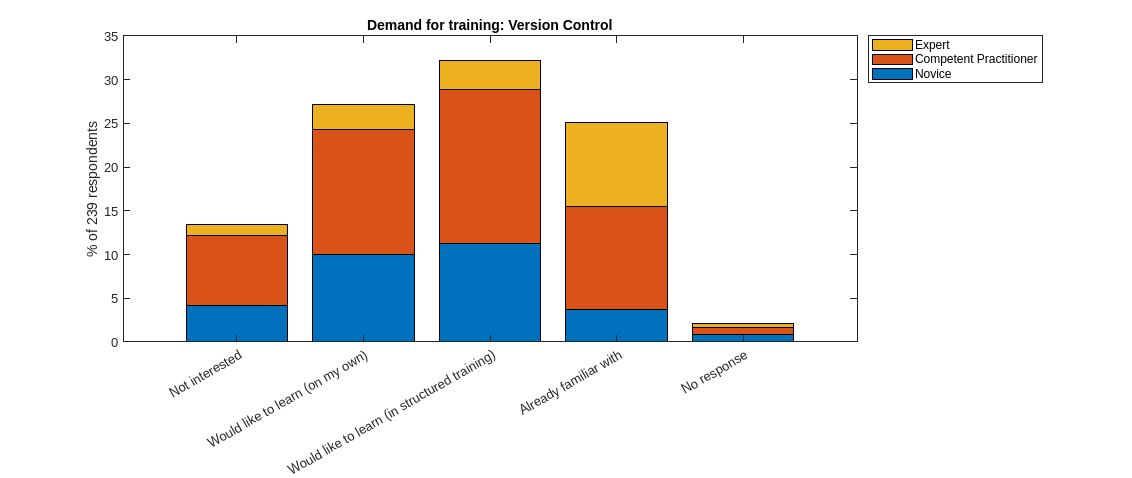

plotTrainingDemand(cleanedData, "trainingDemand_versioncontrol")
title("Demand for training: Version Control")

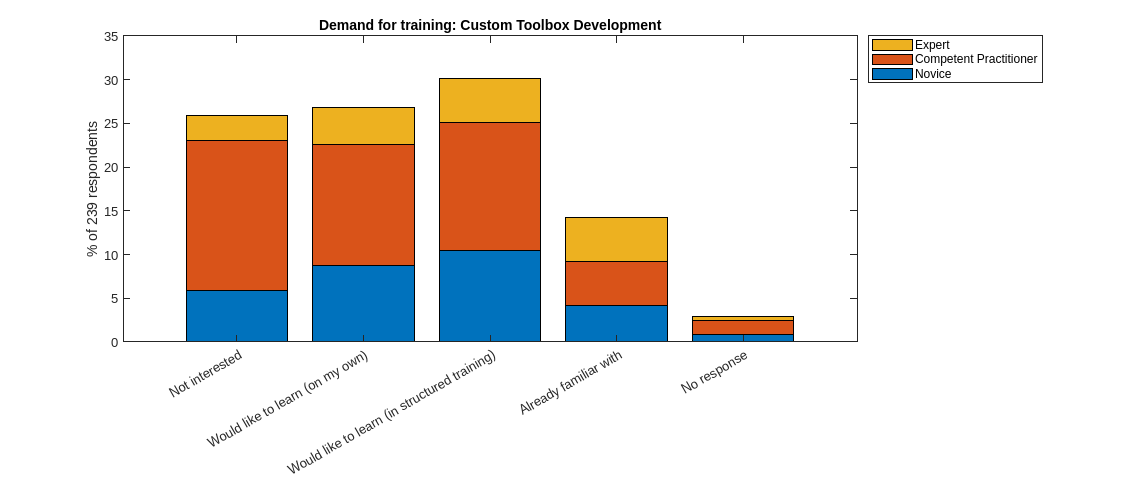

plotTrainingDemand(cleanedData, "trainingDemand_customtoolboxes")
title("Demand for training: Custom Toolbox Development")

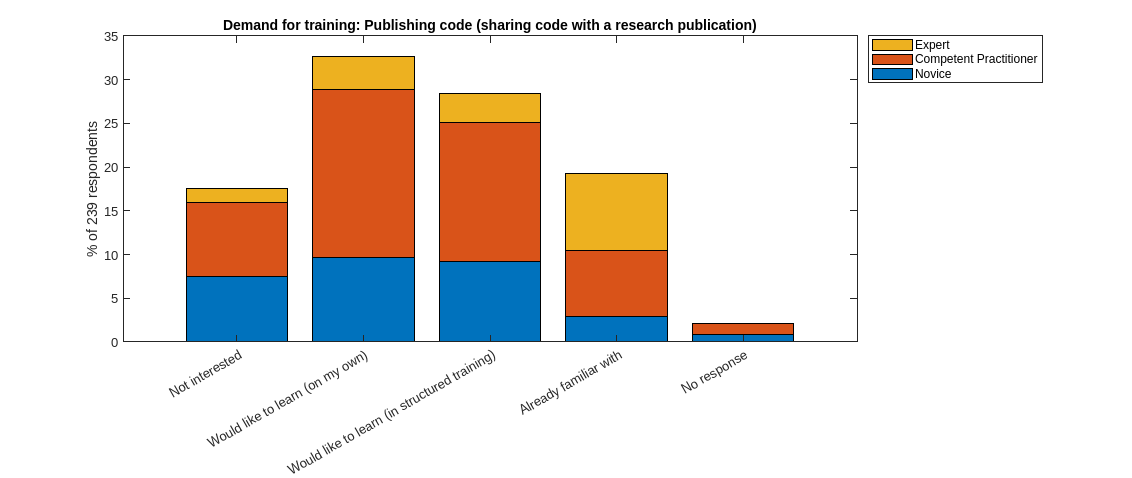

plotTrainingDemand(cleanedData, "trainingDemand_publishingcode")
title("Demand for training: Publishing code (sharing code with a research publication)")

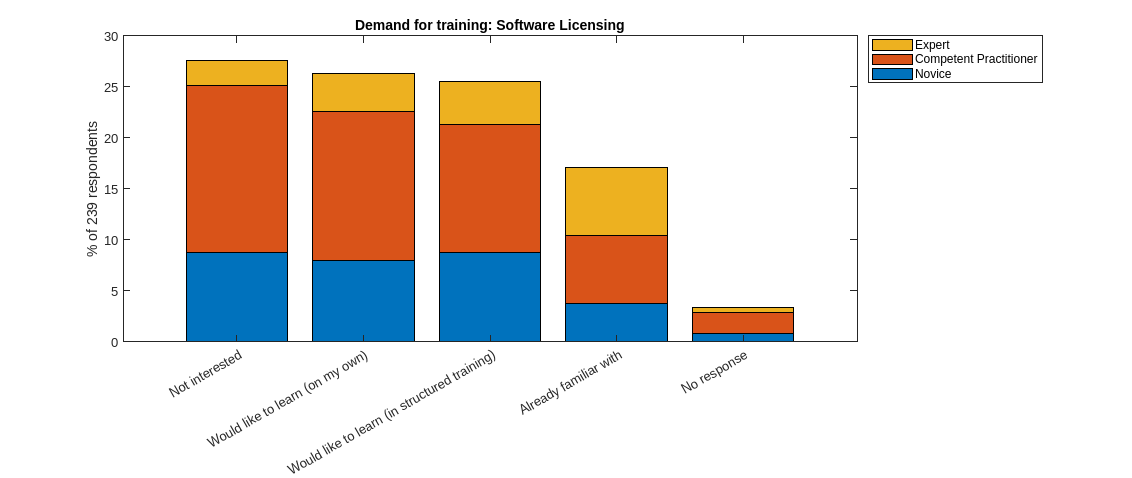

plotTrainingDemand(cleanedData, "trainingDemand_licensing")
title("Demand for training: Software Licensing")

## General Preferences on Training and Guidance

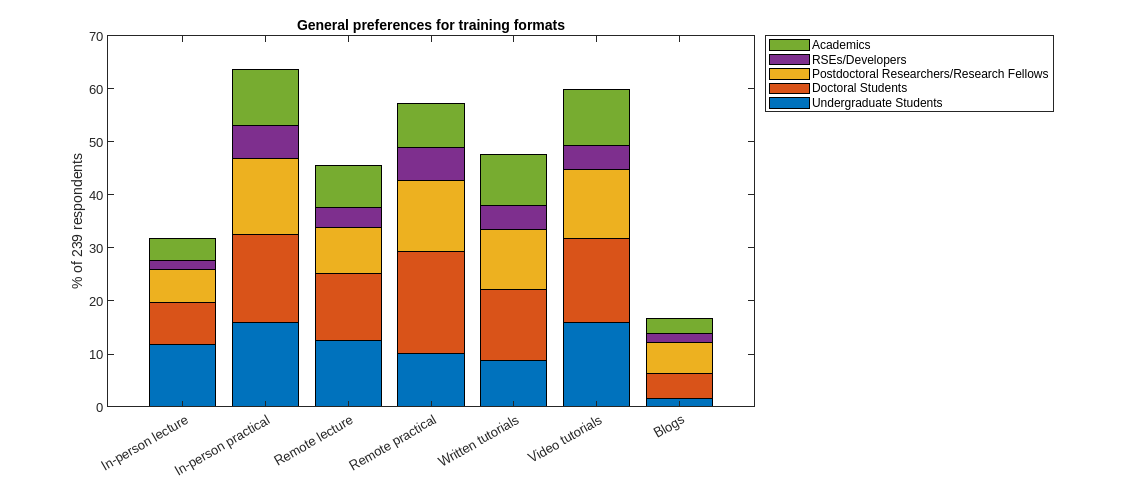

plotTrainingPreferences(cleanedData)
title('General preferences for training formats')

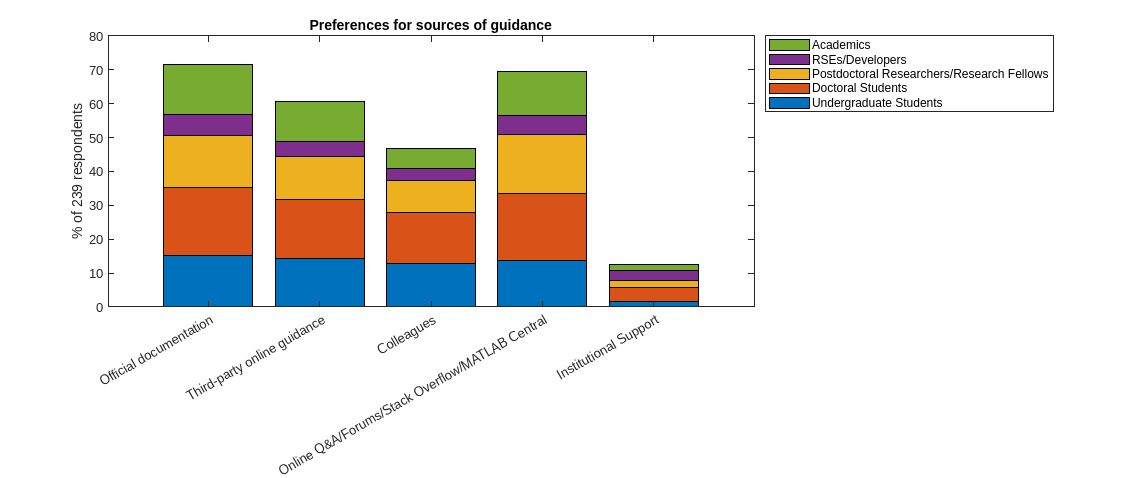

plotGuidancePreferences(cleanedData)
title('Preferences for sources of guidance')